# **TRAINING PARA TODAS LAS FOTOS**

clear all 
close all

% Para optimizarlo y que vaya más rápido
set(0, 'DefaultFigureVisible', 'off'); % Desactivar visualización de figuras
warning('off', 'images:imhistc:inputHasNaNs'); % Desactivar warnings no críticos

files = dir(); % Coger todos los archivos

imageExtensions = {'.jpg', '.tiff'};
textExtension = '.txt';

imageFiles = {};
textFiles = {};

columnas = {
    'ImageName','GlobulosBlancosDetectados', 'ParasitosDetectados', ... 
    'Leu_median_Area', 'Leu_median_BoundingBox','Leu_median_Eccentricity','Leu_median_Circularity','Leu_median_Diameter','Leu_median_Solidity','Leu_median_Perimeter','Leu_median_Intensity' ... 
    'Par_median_Area', 'Par_median_BoundingBox','Par_median_Eccentricity','Par_median_Circularity','Par_median_Diameter','Par_median_Solidity','Par_median_Perimeter','Par_median_Intensity'
};

% Crear una tabla vacía con los nombres de las columnas
Tabla_Global = table('Size', [0, numel(columnas)], 'VariableTypes', repmat({'double'}, 1, numel(columnas)), 'VariableNames', columnas);
Tabla_Global.ImageName = string(Tabla_Global.ImageName); % Cambiar el tipo de ImageName a string

% Separar archivos de imagenes y de texto
for j = 1:length(files)
    [~, name, ext] = fileparts(files(j).name);
    if any(strcmpi(ext, imageExtensions))
        imageFiles{end+1} = files(j).name;
    elseif strcmpi(ext, textExtension)
        textFiles{end+1} = files(j).name;
    end
end

Procesado de cada imagen:


Procesando imagen 1 de 23: 20170728_201358.tiff


alto = 3024

ancho = 12096


parasite_lines =

  0×1 empty cell array



wbc_lines = 20×1 cell array
    {'0-1,White_Blood_Cell,No_Comment,Point,1,2770.6,1333.7'   }
    {'0-10,White_Blood_Cell,No_Comment,Point,1,1913.45,593.95' }
    {'0-11,White_Blood_Cell,No_Comment,Point,1,1892.15,1426.2' }
    {'0-12,White_Blood_Cell,No_Comment,Point,1,1710.75,1511.55'}
    {'0-13,White_Blood_Cell,No_Comment,Point,1,1728.5,1636.05' }
    {'0-14,White_Blood_Cell,No_Comment,Point,1,1575.6,2411.4'  }
    {'0-15,White_Blood_Cell,No_Comment,Point,1,1468.9,2436.25' }
    {'0-16,White_Blood_Cell,No_Comment,Point,1,1308.85,821.55' }
    {'0-17,White_Blood_Cell,No_Comment,Point,1,1376.4,978.05'  }
    {'0-18,White_Blood_Cell,No_Comment,Point,1,1280.4,1262.6'  }
    {'0-19,White_Blood_Cell,No_Comment,Point,1,810.9,1415.5'   }
    {'0-2,White_Blood_Cell,No_Comment,Point,1,2820.4,1593.35'  }
    {'0-20,White_Blood_Cell,No_Comment,Point,1,917.6,2265.55'  }
    {'0-3,White_Blood_Cell,No_Comment,Point,1,2916.45,1732.05' }
    {'0-4,White_Blood_Cell,No_Comment,Point,1,3076.5,2308.25' 

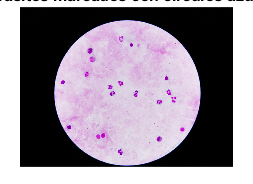

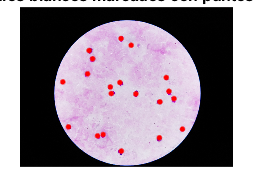

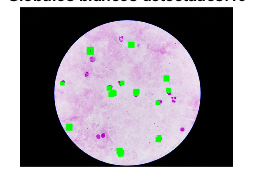

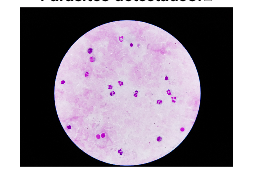

Unrecognized function or variable 'par_validos'.

for imgIdx = 1:length(imageFiles)
    I = imread(imageFiles{imgIdx});

    par_validos = false(0);
    wbc_validos = false(0);
    
    fprintf('\nProcesando imagen %d de %d: %s\n', imgIdx, length(imageFiles), imageFiles{imgIdx});
    %disp(['Tamaño original de la imagen: ', num2str(size(I))]);

    % 1. Convertir a escala de grises
    [alto, ancho] = size(I);
    I_double = im2double(I);
    I_gris = rgb2gray(I);
    I_gris_double = im2double(I_gris);

    % 2. Aplicar filtros
    I_Gauss = imgaussfilt(I_double);
    I_Gauss_double = im2double(I_Gauss);
    figure;
    %subplot(1,2,1); imshow(I); title(['Original: ', imageFiles{imgIdx}]);
    %subplot(1,2,2); imshow(I_Gauss); title('Gauss');

    % Buscar el archivo de texto correspondiente
    [~, baseName, ~] = fileparts(imageFiles{imgIdx});
%     correspondingTextFile = [baseName, textExtension];
    baseNameClean = strrep(baseName, '_', ''); % para que si no tienen _ tambien los coja
    correspondingTextFile = '';
    for t = 1:length(textFiles)
        [~, textBaseName, ~] = fileparts(textFiles{t});
        textBaseNameClean = strrep(textBaseName, '_', '');
        if strcmpi(baseNameClean, textBaseNameClean)
            correspondingTextFile = textFiles{t};
            break;
        end
    end


     %if ismember(correspondingTextFile, textFiles)
     if ~isempty(correspondingTextFile)
        % Leer el archivo de texto
        textContent = fileread(correspondingTextFile);
        %fprintf('Archivo de texto encontrado: %s\n', correspondingTextFile);
        

        [alto, ancho] = size(I_Gauss)
        lines = splitlines(textContent); 
        % Tabla 1
        lines1 = lines(1);
        dims = str2double(split(lines1, ','));
        table_dims = array2table(dims');
        % Tabla 2 
        parasite_lines = lines(contains(lines, 'Parasite') | contains(lines, 'Parasitized'))
        if isempty (parasite_lines)
            parasite_data = cell(0,9);
            num_parasitos = 0;
        else
            parasite_data = cell(length(parasite_lines), 9);
            for parIdx = 1:length(parasite_lines)
                parts = strsplit(parasite_lines{parIdx}, ',');
                parasite_data(parIdx,:) = parts(1:9);
            end
        end     
        parasite_table = cell2table(parasite_data);
        % Tabla 3
        wbc_lines = lines(contains(lines, 'White_Blood_Cell'))
        wbc_data = cell(length(wbc_lines), 7);
        for wbcIdx = 1:length(wbc_lines)
            parts = strsplit(wbc_lines{wbcIdx}, ',');
            wbc_data(wbcIdx,:) = parts(1:7);
        end
        wbc_table = cell2table(wbc_data);

        % Parasitos marcados
        Parasitos_Anotaciones_Figura = figure;
        imshow(I_Gauss);
        hold on;
        x_centers = str2double(parasite_data(:,6));
        y_centers = str2double(parasite_data(:,7));
        x_perim = str2double(parasite_data(:,8));
        y_perim = str2double(parasite_data(:,9));
        radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);
        for i = 1:length(x_centers)
            % Dibujar círculo con centro (x_centers(i), y_centers(i)) y radio radios(i)
            viscircles([x_centers(i), y_centers(i)], radios(i), 'Color', 'blue', 'LineWidth', 1);
            
            % Opcional: marcar el centro con un punto
            %plot(x_centers(i), y_centers(i), 'b+', 'MarkerSize', 10, 'LineWidth', 2);
            
            % Opcional: marcar el punto del perímetro
            %plot(x_perim(i), y_perim(i), 'bo', 'MarkerSize', 8, 'LineWidth', 1);
        end
        hold off;
        title('Parásitos marcados con círculos azules');
        % White Blood Cells marcados
        Leucocitos_Anotaciones_Figura = figure;
        imshow(I_Gauss);
        hold on; 
        x_coords = str2double(wbc_table{:,6});
        y_coords = str2double(wbc_table{:,7});
        plot(x_coords, y_coords, 'r.', 'MarkerSize', 10);
        hold off;
        title('Glóbulos blancos marcados con puntos rojos');


        else
        fprintf('No se encontró archivo de texto para: %s\n', imageFiles{i});
     end

    % Otsu
    A = mean(im2double(I_Gauss), 3); % Promedia los 3 canales RGB --> transforma a grises
    %A = adapthisteq(mean(im2double(I_Gauss),3));
    TO = graythresh(A); % Umbral óptimo de Otsu
    C = A > TO; % Crear una imagen binaria: blanco si es mayor al umbral y negro si no
    %figure;
    %imshow(C);
    %title('Otsu'); 
    
    %%% Para contar las zonas negras (los glóbulos blancos)
    BW_invert = ~C; % Invierte la imagen (blanco a negro y negro a blanco)
    BW_clean = bwareaopen(BW_invert, 50); % Quita ruido pequeño (con menos de 50 pixeles)
    [L, num] = bwlabel(BW_clean); % Etiqueta los objetos conectados = se identifican las zonas grandes
    
    stats = regionprops(L, 'Area', 'Centroid', 'BoundingBox');
    min_area = 100;
    max_area = 30000;
    mask_filtered = false(size(BW_clean));
    for k = 1:num
        if stats(k).Area > min_area && stats(k).Area < max_area
            mask_filtered(L == k) = true;
        end
    end % Nos quedamos con las formas que tienen un tamaño razoable = glóbulos blancos
    
    [L_filtered, num_filtered] = bwlabel(mask_filtered);
    stats_filtered = regionprops(L_filtered, 'Area', 'Centroid', 'BoundingBox');

    figure;
    imshow(I_Gauss); hold on;
    for k = 1:num_filtered
        rectangle('Position', stats_filtered(k).BoundingBox,'EdgeColor','g','LineWidth',2);
    end
    hold off;
    title(['Globulos blancos detectados:', num2str(num_filtered)]);

    globulos_blancos_detectados = num2str(num_filtered);

    % Para contar parásitos
    radio_dilatacion = 20;
    se = strel('disk', radio_dilatacion);
    mascara_dilatada = imdilate(mask_filtered, se);

    fondo_promedio = mean(mean(I_Gauss(1:10, :, :)));
    I_Gauss_sin_globulos = I_Gauss;
    for c = 1:3
        canal = I_Gauss(:,:,c);
        canal(mascara_dilatada) = fondo_promedio(c);
        I_Gauss_sin_globulos(:,:,c) = canal;
    end


    I_gray = rgb2gray(I_Gauss_sin_globulos);
    I_contrast = adapthisteq(I_gray);
    th = graythresh(I_contrast);
    BW = imbinarize(I_contrast, th);
    BW = imopen(~BW, strel('disk', 1));
    BW_clean = bwareaopen(BW, 30); % Preparamos la imagen para detectar parásitos, resaltándolos y limpiando el ruido
    
    [L, num] = bwlabel(BW_clean);
    stats = regionprops(L, 'Area', 'BoundingBox','Centroid','EquivDiameter');
    min_area_parasitos = 20;
    max_area_parasitos = 1000;
    mask_filtered_parasitos = false(size(BW_clean));
    for k = 1:num
        if stats(k).Area > min_area_parasitos && stats(k).Area < max_area_parasitos
            mask_filtered_parasitos(L == k) = true;
        end
    end
    
    [L_filtered_parasitos, num_filtered_parasitos] = bwlabel(mask_filtered_parasitos);
    
    stats_filtered_parasitos = regionprops(L_filtered_parasitos, 'BoundingBox','Centroid','EquivDiameter');
    centros = cat(1, stats_filtered_parasitos.Centroid);
    radios = [stats_filtered_parasitos.EquivDiameter] / 2;
    
    figure;
    imshow(I_Gauss); hold on;
    if ~isempty(parasite_data)
        centros = cat(1, stats_filtered_parasitos.Centroid);
        radios = [stats_filtered_parasitos.EquivDiameter] / 2;
        viscircles(centros, radios', 'Color','r','LineWidth',1);
        plot(centros(:,1), centros(:,2),'r.','MarkerSize',10);

        x_centers = str2double(parasite_data(:,6));
        y_centers = str2double(parasite_data(:,7));
        x_perim = str2double(parasite_data(:,8));
        y_perim = str2double(parasite_data(:,9));
        radios = sqrt(x_perim - x_centers).^2 + (y_perim - y_centers.^2);
        for i = 1:length(x_centers)
            if radios(i) > 0 
                viscircles([x_centers(i), y_centers(i)], radios(i), 'Color','blue','LineWidth',1);
        
            end
        end
    end
    hold off;
    title(['Parasitos detectados:', length(stats_filtered)]);
    % AZUL = REAL ////// VERDE = ESTIMADO

    %if isempty(parasite_data)
     %   num_parasitos = 0; % Asignamos 0 si no hay anotaciones de parásitos
    %end


    % ========== DETECCIÓN PRECISA =========== %
    % Glóbulos blancos
    umbral_distancia_leu = 400; % Ajustar
    centroides_wbc_detectados = cat(1, stats_filtered.Centroid);
    anotaciones_wbc = [str2double(wbc_table{:,6}), str2double(wbc_table{:,7})];
    coincidencias_wbc = zeros(size(anotaciones_wbc, 1), 1);
    wbc_validos = false(size(centroides_wbc_detectados, 1), 1);
    for i = 1:size(anotaciones_wbc, 1)
        distancias = sqrt(sum((centroides_wbc_detectados - anotaciones_wbc(i,:)).^2, 2));
        [min_dist, idx] = min(distancias);
        if min_dist < umbral_distancia_leu
            coincidencias_wbc(i) = idx;
            wbc_validos(idx) = true;
        end
    end

    % Parásitos
    umbral_distancia_par = 500; % Ajustar
    if ~isempty(parasite_data)
        centroides_par_detectados = cat(1, stats_filtered_parasitos.Centroid);
        anotaciones_par = [str2double(parasite_data(:,6)), str2double(parasite_data(:,7))];
        coincidencias_par = zeros(size(anotaciones_par, 1), 1);
        par_validos = false(length(stats_filtered_parasitos), 1);
        
        for i = 1:size(anotaciones_par, 1)
            distancias = sqrt(sum((centroides_par_detectados - anotaciones_par(i,:)).^2, 2));
            [min_dist, idx] = min(distancias);
            if min_dist < umbral_distancia_par
                coincidencias_par(i) = idx;
                par_validos(idx) = true;
            end
        end
    end

    % Para casos donde hay 0
    if ~isempty(stats_filtered) && any(wbc_validos)
        stats_filtered_nuevo = stats_filtered(wbc_validos);
    else
        stats_filtered_nuevo = [];
    end
    if isempty(stats_filtered_parasitos)
        stats_filtered_parasitos_nuevo = [];
    else
        % Asegurar que par_validos tenga la longitud correcta
        if length(par_validos) ~= length(stats_filtered_parasitos)
            par_validos = false(length(stats_filtered_parasitos), 1);
        end
        
        if any(par_validos)
            stats_filtered_parasitos_nuevo = stats_filtered_parasitos(par_validos);
        else
            stats_filtered_parasitos_nuevo = [];
        end
    end


%     % Filtrar
%     stats_filtered_nuevo = stats_filtered(wbc_validos);
%     stats_filtered_parasitos_nuevo = stats_filtered_parasitos(par_validos);
    
    % Actualizar conteos
    leucocitos_validos = sum(wbc_validos)
    parasitos_validos = sum(par_validos)

    % Visualización
    figure; 
    imshow(I); 
    hold on;
    
    % Dibujar anotaciones reales
    if ~isempty(wbc_table)
        plot(str2double(wbc_table{:,6}), str2double(wbc_table{:,7}), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if ~isempty(parasite_data)
        plot(str2double(parasite_data(:,6)), str2double(parasite_data(:,7)), 'yo', 'MarkerSize', 10, 'LineWidth', 2);
    end
    
    % Dibujar detecciones válidas
    if ~isempty(stats_filtered_nuevo)
        centros_wbc = cat(1, stats_filtered_nuevo.Centroid);
        plot(centros_wbc(:,1), centros_wbc(:,2), 'r.', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if ~isempty(stats_filtered_parasitos_nuevo)
        centros_par = cat(1, stats_filtered_parasitos_nuevo.Centroid);
        plot(centros_par(:,1), centros_par(:,2), 'b.', 'MarkerSize', 10, 'LineWidth', 2);
    end
    
    legend('Anot. WBC', 'Anot. Parásitos', 'Detect. WBC', 'Detect. Parásitos');
    title('Comparación detecciones vs anotaciones');
    hold off;

    % ========================================= %




    % NUEVO
%     stats_filtered_nuevo = regionprops(mask_filtered, A, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
%     stats_filtered_parasitos_nuevo = regionprops(mask_filtered_parasitos, A, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');

    Label_leu = bwlabel(mask_filtered);
    mask_leu_validos = false(size(mask_filtered));
    labels_leu_validos = find(wbc_validos);
    for k = 1:length(labels_leu_validos)
        mask_leu_validos(Label_leu == labels_leu_validos(k)) = true;
    end
    stats_filtered_nuevo = regionprops(mask_leu_validos, A, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');

    L_par = bwlabel(mask_filtered_parasitos);
    mask_par_validos = false(size(mask_filtered_parasitos));
    labels_par_validos = find(par_validos);
    
    for k = 1:length(labels_par_validos)
        mask_par_validos(L_par == labels_par_validos(k)) = true;
    end
    
    stats_filtered_parasitos_nuevo = regionprops(mask_par_validos, A, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');


    % Características de glóbulos blancos detectados
    if ~isempty(stats_filtered_nuevo)
        Globulos_Blancos_Caracteristicas = struct2table(stats_filtered_nuevo);
    else
        Globulos_Blancos_Caracteristicas = table();
    end
        
    % Características de parásitos detectados
    if ~isempty(stats_filtered_parasitos_nuevo)
        Parasitos_Caracteristicas = struct2table(stats_filtered_parasitos_nuevo);
    else
        Parasitos_Caracteristicas = table();
    end

    % Crear nueva fila para la tabla global
    nueva_fila = table();
    nueva_fila.ImageName = string(imageFiles{imgIdx});
    nueva_fila.GlobulosBlancosDetectados = height(Globulos_Blancos_Caracteristicas);
    nueva_fila.ParasitosDetectados = height(Parasitos_Caracteristicas);


%     % Datos tabulares
%     % Glóbulos blancos
%     x_coords = str2double(wbc_table{:,6});
%     y_coords = str2double(wbc_table{:,7});
%     
%     % Usamos la imagen original porque es de donde se han sacado las anotaciones
%     
%     % Creamos ROI (Región de Interés --> una ventana)
%     ROI = 50; % IR AJUSTANDO!!!!!
%     
%     Globulos_Blancos_Caracteristicas = table();
%     for k = 1:length(x_coords)
%         x = round(x_coords(k));
%         y = round(y_coords(k));
%     
%         % Definir ROI alrededor del punto
%         x_min = max(x - ROI, 1); % queremos ir desde x - ROI pero si x está cerca del borde izk nos da negativo, asi que tiene que ser el maximo
%         x_max = min(x + ROI, size(I,2));
%         y_min = max(y - ROI, 1);
%         y_max = min(y + ROI, size(I,1));
%     
%         % Extraer ROI de cada canal
%         roi_rgb = I(y_min:y_max, x_min:x_max, :);
%         roi_gray = I_gray(y_min:y_max, x_min:x_max); 
%     
%         % Umbralizar
%         roi_bin = imbinarize(roi_gray, 'adaptive', 'Sensitivity', 0.4);
%         roi_bin = imopen(roi_bin, strel('disk', 2));
%     
%         % Etiquetar componentes detectados
%         [L_roi, ~] = bwlabel(roi_bin);
%         stats = regionprops(L_roi, roi_gray, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
%         
%         % Dentro de ROI nos quedamos con el objeto más grande = globulo blanco
%         if ~isempty(stats)
%             [~, idx_max] = max([stats.Area]);
%             s = stats(idx_max);
%     
%             % Guardar características en tabla
%             Globulos_Blancos_Caracteristicas = [Globulos_Blancos_Caracteristicas; struct2table(s)]; % con struct2table(s) convertimos las propiedades del objeto (s) en una fila de la tabla
%         end 
%     end
% 
%     % Parásitos
%     x_centers = str2double(parasite_data(:,6));
%     y_centers = str2double(parasite_data(:,7));
%     x_perim = str2double(parasite_data(:,8));
%     y_perim = str2double(parasite_data(:,9));
%     radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);
%     
%     % Usamos la imagen original porque es de donde se han sacado las anotaciones
%     
%     Parasitos_Caracteristicas = table();
%     for w = 1:length(x_centers)
%         x = round(x_centers(w));
%         y = round(y_centers(w));
%         r = ceil(radios(w));
%     
%         % Definir ROI cuadrado que tenga el circulo dentro
%         x_min = max(x - r, 1); % queremos ir desde x - ROI pero si x está cerca del borde izk nos da negativo, asi que tiene que ser el maximo
%         x_max = min(x + r, size(I,2));
%         y_min = max(y - r, 1);
%         y_max = min(y + r, size(I,1));
%     
%         % Extraer ROI de cada canal
%         roi_gray_parasitos = I_gray(y_min:y_max, x_min:x_max);
%     
%         % Máscara del tamaño de ROI
%         [cols, rows] = meshgrid(x_min:x_max, y_min:y_max);
%         mask = (cols - x).^2 + (rows - y).^2 <= r^2;
%     
%         % Umbralización dentro de la máscara
%         roi_masked = roi_gray;
%         roi_masked(~mask) = 0;  % Fuera del círculo = negro
%         roi_bin = imbinarize(roi_masked, 'adaptive', 'Sensitivity', 0.4);
%         roi_bin = imopen(roi_bin, strel('disk', 1));
%     
%         % Etiquetar componentes detectados
%         L_roi = bwlabel(roi_bin);
%         stats = regionprops(L_roi, roi_masked, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
%         
%         if ~isempty(stats)
%             [~, idx_max] = max([stats.Area]);
%             s = stats(idx_max);
%     
%             % Guardar características en tabla
%             Parasitos_Caracteristicas = [Parasitos_Caracteristicas; struct2table(s)]; % con struct2table(s) convertimos las propiedades del objeto (s) en una fila de la tabla
%         end 
%     end
% 
%     % Crear nueva fila para la tabla global
%     nueva_fila = table();
%     nueva_fila.ImageName = string(imageFiles{imgIdx});
%     %nueva_fila.GlobulosBlancosDetectados = height(Globulos_Blancos_Caracteristicas)
%     nueva_fila.GlobulosBlancosDetectados = height(Globulos_Blancos_Caracteristicas);
%     nueva_fila.ParasitosDetectados = height(Parasitos_Caracteristicas);


    % Añadir medianas
    
    %%% Glóbulos blancos
    if ~isempty(Globulos_Blancos_Caracteristicas)
        %medianas_leucocitos = varfun(@median, stats_filtered_nuevo);
        nueva_fila.Leu_median_Area = median(Globulos_Blancos_Caracteristicas.Area);
        nueva_fila.Leu_median_BoundingBox = median(Globulos_Blancos_Caracteristicas.BoundingBox);
        nueva_fila.Leu_median_Eccentricity = median(Globulos_Blancos_Caracteristicas.Eccentricity);
        nueva_fila.Leu_median_Circularity = median(Globulos_Blancos_Caracteristicas.Circularity);
        nueva_fila.Leu_median_Diameter = median(Globulos_Blancos_Caracteristicas.EquivDiameter);
        nueva_fila.Leu_median_Solidity = median(Globulos_Blancos_Caracteristicas.Solidity);
        nueva_fila.Leu_median_Perimeter = median(Globulos_Blancos_Caracteristicas.Perimeter);
        nueva_fila.Leu_median_Intensity = median(Globulos_Blancos_Caracteristicas.MeanIntensity);
    else
        nueva_fila.Leu_median_Area = NaN;
        nueva_fila.Leu_median_BoundingBox = NaN;
        nueva_fila.Leu_median_Eccentricity = NaN;
        nueva_fila.Leu_median_Circularity = NaN;
        nueva_fila.Leu_median_Diameter = NaN;
        nueva_fila.Leu_median_Solidity = NaN;
        nueva_fila.Leu_median_Perimeter = NaN;
        nueva_fila.Leu_median_Intensity = NaN;

    end


    %%% Parásitos
    if ~isempty(Parasitos_Caracteristicas)
        %medianas_parasitos = varfun(@median, Parasitos_Caracteristicas);
        nueva_fila.Par_median_Area = median(Parasitos_Caracteristicas.Area);
        %nueva_fila.Par_median_BoundingBox = median(Parasitos_Caracteristicas.BoundingBox);
        if height(Parasitos_Caracteristicas) == 1
            nueva_fila.Par_median_BoundingBox = Parasitos_Caracteristicas.BoundingBox;
        else
            nueva_fila.Par_median_BoundingBox = median(Parasitos_Caracteristicas.BoundingBox);
        end
        nueva_fila.Par_median_Eccentricity = median(Parasitos_Caracteristicas.Eccentricity);
        nueva_fila.Par_median_Circularity = median(Parasitos_Caracteristicas.Circularity);
        nueva_fila.Par_median_Diameter = median(Parasitos_Caracteristicas.EquivDiameter);
        nueva_fila.Par_median_Solidity = median(Parasitos_Caracteristicas.Solidity);
        nueva_fila.Par_median_Perimeter = median(Parasitos_Caracteristicas.Perimeter);
        nueva_fila.Par_median_Intensity = median(Parasitos_Caracteristicas.MeanIntensity);
    else
        nueva_fila.Par_median_Area = NaN;
        nueva_fila.Par_median_BoundingBox = [NaN, NaN, NaN, NaN];
        nueva_fila.Par_median_Eccentricity = NaN;
        nueva_fila.Par_median_Circularity = NaN;
        nueva_fila.Par_median_Diameter = NaN;
        nueva_fila.Par_median_Solidity = NaN;
        nueva_fila.Par_median_Perimeter = NaN;
        nueva_fila.Par_median_Intensity = NaN;
    end
    % Añadir la nueva fila a la tabla global
    Tabla_Global = [Tabla_Global; nueva_fila];
end


% Eliminar posibles duplicados (por si acaso)
[~, idx] = unique(Tabla_Global.ImageName, 'stable');
Tabla_Global = Tabla_Global(idx,:);

writetable(Tabla_Global, 'Falciparum_Data.csv');

fprintf('\nProcesamiento completado para todas las imágenes.\n');
display(Tabla_Global);